# TODO: Title

## Wyczyszczenie danych skryptu, dodanie folderu z narzędziami do zmiennej środowiskowej

clear variables;
addpath([ pwd, '/MATLAB_SM-Toolbox_1.0' ]);

## Wybór typu operacji

disp('Wybierz typ operacji: ');

Wybierz typ operacji: 


disp('1. Macierz samopodobieństwa utworu');

1. Macierz samopodobieństwa utworu


disp('2. Macierz podobieństwa dwóch utworów');

2. Macierz podobieństwa dwóch utworów


type = input('');

## Pobranie od użytkownika ścieżek do plików

path1 = input('Podaj ścieżkę do pierwszego pliku: ');
file1 = input('Podaj nazwę pierwszego pliku: ');    
    
if type == 1
    path2 = path1;
    file2 = file1;
else
    path2 = input('Podaj ścieżkę do drugiego pliku: ');
    file2 = input('Podaj nazwę drugiego pliku: ');
end

## Przygotowanie pliku do analizy

pitch_parameters.winLenSTMSP = 4410;
CENS_parameters.winLenSmooth = 11;
CENS_parameters.downsampSmooth = 5;
visualization_parameters.colormapPreset = 2;
threshold_parameters.threshTechnique = 1;
threshold_parameters.threshValue = 0.75;
threshold_parameters.applyBinarize = 1;

audio1 = wav_to_audio('', path1, file1);
pitch1 = audio_to_pitch_via_FB(audio1, pitch_parameters);

Computing subbands and STMSP for all pitches: (21-108):  108


cens1 = pitch_to_CENS(pitch1, CENS_parameters);

if type == 1
    audio2 = audio1;
    pitch2 = pitch1;
    cens2 = cens1;
else
    audio2 = wav_to_audio('', path2, file2);
    pitch2 = audio_to_pitch_via_FB(audio2, pitch_parameters);
    cens2 = pitch_to_CENS(pitch2, CENS_parameters);
end

## Generacja macierzy podobieństwa

SM = features_to_SM(cens1, cens2);
SM_Thresholded = threshSM(SM, threshold_parameters);

## Wyświetlenie macierzy podobieństwa

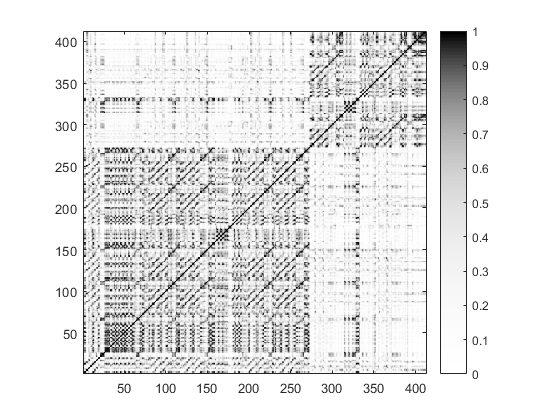

visualizeSM(SM, visualization_parameters);

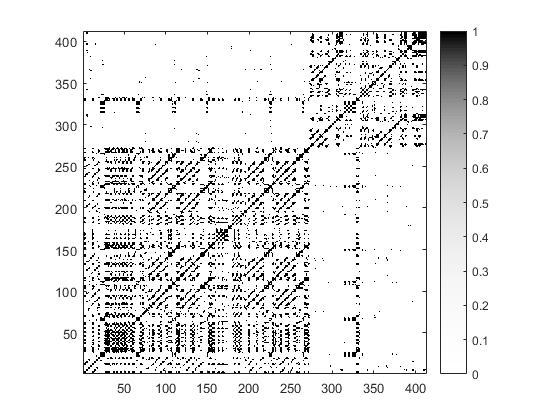

visualizeSM(SM_Thresholded, visualization_parameters);